# Season 1: Mathematical Foundations for Modern Control

**Prerequisites:** Basic linear algebra

**MATLAB Version:** R2025b

**Toolboxes Required:** Symbolic Math Toolbox

close all; clear; clc;
rng(0);  % For reproducibility

## Section 0:

Basic Matlab Functions:

### Basic arithmetic operators

Addition = 2 + 3

Addition = 5

Subtraction = 2 - 3

Subtraction = -1

Multiplication = 2 * 3

Multiplication = 6

Division = 2 / 3

Division = 0.6667

syms x y;

x = 2 + 3 * 4

x = 14

x = (2 + 3) * 4

x = 20

y = 1 / (2 + 3^2) + 4/5 * 6/7

y = 0.7766

y = 1 / 2 + 3^2 + 4/5 * 6/7

y = 10.1857

### Mathematical functions

rad2deg(1)       % Radians to Degrees

ans = 57.2958

deg2rad(90)      % Degrees to Radians

ans = 1.5708

cosine_val = cos(x)  % Cosine 

cosine_val = 0.4081

sine_val = sin(x)    % Sine 

sine_val = 0.9129

tan_val = tan(x)     % Tangent 

tan_val = 2.2372

arcc_val = acos(x)   % Arc cosine

arcc_val = 0.0000 + 3.6883i

arcs_val = asin(x)   % Arc sine 

arcs_val = 1.5708 - 3.6883i

arct_val = atan(x)   % Arc tangent

arct_val = 1.5208

exp_val = exp(x)     % Exponential 

exp_val = 4.8517e+08

sqrt_val = sqrt(x)   % Square root

sqrt_val = 4.4721

log_val = log(x)     % Natural 

log_val = 2.9957

log10_val = log10(x) % Common logarithm

log10_val = 1.3010

x = -20;
abs_val = abs(x)     % Absolute value

abs_val = 20

sign_val = sign(x)   % Signum function

sign_val = -1

x = [1 2 3 7 465 -2 7.6];
max_val = max(x)     % Maximum value

max_val = 465

min_val = min(x)     % Minimum value

min_val = -2

x = 45.3;
ceil_val = ceil(x)   % Round towards +∞

ceil_val = 46

floor_val = floor(x) % Round towards −∞

floor_val = 45

round_val = round(x) % Round to nearest integer

round_val = 45

x = 2 + 7i;
real(x)

ans = 2

imag(x)

ans = 7

angle_val = angle(x) % Phase angle

angle_val = 1.2925

conj_val = conj(x)   % Complex conjugate

conj_val = 2.0000 - 7.0000i

### Matrix

A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


A(2,1)

ans = 4

A(3,3) = 0

A =      1     2     3
     4     5     6
     7     8     0


m = 2;
n = 3;
eye1 = eye(m,n)    % Returns an m-by-n matrix with 1 on the main diagonal

eye1 =      1     0     0
     0     1     0


eye2 = eye(n)      % Returns an n-by-n square identity matrix

eye2 =      1     0     0
     0     1     0
     0     0     1


zeros_example = zeros(m,n) % Returns an m-by-n matrix of zeros

zeros_example =      0     0     0
     0     0     0


ones_example = ones(m,n)   % Returns an m-by-n matrix of ones

ones_example =      1     1     1
     1     1     1


diag_example = diag(A)     % Extracts the diagonal of matrix A

diag_example =      1
     5
     0


rand_example = rand(m,n)   % Returns an m-by-n matrix of random numbers

rand_example =     0.8147    0.1270    0.6324
    0.9058    0.9134    0.0975


## Section 1.1: Vector and Matrix Operations

### **Concept Overview**

Matrix operations form the foundation of state-space control theory. Understanding element-wise operations, matrix multiplication, and basic matrix properties is essential for analyzing linear systems.

% Create sample matrices
A = [1 2 3; 4 5 6; 7 8 10];

fprintf('Matrix A:\n'); % Use fprintf to write data to the screen or a text file, refer to the documentation for writing to a text file

Matrix A:


disp(A); % display the output without the variable name

     1     2     3
     4     5     6
     7     8    10




B = [2 1 0; 1 3 1; 0 1 2]

B =      2     1     0
     1     3     1
     0     1     2


disp(B);

     2     1     0
     1     3     1
     0     1     2



v = [1; 2; 3];


### Basic matrix operations

A + B (addition)

C_add = A + B

C_add =      3     3     3
     5     8     7
     7     9    12


A * B (matrix multiplication):

C_mult = A * B

C_mult =      4    10     8
    13    25    17
    22    41    28


A .* B (element-wise multiplication):

C_elem = A .* B  

C_elem =      2     2     0
     4    15     6
     0     8    20


A.^2 (Element-wise power)

C_power = A.^2  

C_power =      1     4     9
    16    25    36
    49    64   100


Transpose operations

A_transpose = A.'       % Non-conjugate transpose

A_transpose =      1     4     7
     2     5     8
     3     6    10


A_hermitian = A'        % Conjugate transpose (same for real matrices)

A_hermitian =      1     4     7
     2     5     8
     3     6    10


Matrix concatenation

H_concat = [A, B]       % Horizontal concatenation

H_concat =      1     2     3     2     1     0
     4     5     6     1     3     1
     7     8    10     0     1     2


V_concat = [A; B]       % Vertical concatenation

V_concat =      1     2     3
     4     5     6
     7     8    10
     2     1     0
     1     3     1
     0     1     2


## Section 1.2: Matrix Properties and Functions

**Mathematical Background**

Key matrix properties:

- Determinant: det(A) - nonzero for invertible matrices

- Rank: number of linearly independent rows/columns

- Trace: sum of diagonal elements, tr(A) = sum of eigenvalues

- Inverse: A^(-1) exists if det(A) ≠ 0

Determinant

det_A = det(A);
fprintf('Determinant of A: %.4f\n', det_A);

Determinant of A: -3.0000


Rank

rank_A = rank(A);
fprintf('Rank of A: %d (size %dx%d)\n', rank_A, size(A,1), size(A,2));

Rank of A: 3 (size 3x3)


Trace (*Sum of diagonal elements)*

trace_A = trace(A);
fprintf('Trace of A: %.4f\n', trace_A);

Trace of A: 16.0000


Inverse (if exists)

if det_A ~= 0
    A_inv = inv(A);
    fprintf('Inverse of A:\n');
    disp(A_inv);
    
    % Verify A * inv(A) = I
    identity_check = A * A_inv;
    fprintf('A * inv(A) (should be identity):\n');
    disp(identity_check);
else
    fprintf('Matrix A is singular (not invertible)\n');
end

Inverse of A:


   -0.6667   -1.3333    1.0000
   -0.6667    3.6667   -2.0000
    1.0000   -2.0000    1.0000



A * inv(A) (should be identity):


    1.0000         0   -0.0000
         0    1.0000         0
         0         0    1.0000



### Condition number (measures sensitivity to perturbations)

A *condition number* for a matrix and computational task measures how sensitive the answer is to changes in the input data and roundoff errors in the solution process.

The *condition number for inversion* of a matrix measures the sensitivity of the solution of a system of linear equations to errors in the data. It gives an indication of the accuracy of the results from matrix inversion and the linear equation solution. For example, the 2-norm condition number of a square matrix is


$$\kappa (A)=\|A
\|\|A
-1
\|\,.$$


In this context, a large condition number indicates that a small change in the coefficient matrix `A` can lead to larger changes in the output `b` in the linear equations *A**x* = *b* and *x**A* = *b*. The extreme case is when `A` is so poorly conditioned that it is singular (an infinite condition number), in which case it has no inverse and the linear equation has no unique solution.

cond_A = cond(A);
fprintf('Condition number of A: %.4f\n', cond_A);

Condition number of A: 88.4483


fprintf('(Higher values indicate ill-conditioning)\n\n');

(Higher values indicate ill-conditioning)



## Section 1.3: Matrix Norms

**Concept Overview**

Matrix norms measure the "size" of a matrix and are crucial for:

- Stability analysis

- Error bounds in numerical computations

- Convergence analysis

**Common Norms:**

- 1-norm: maximum absolute column sum

- 2-norm (spectral): largest singular value

- ∞-norm: maximum absolute row sum

- Frobenius norm: sqrt(sum of squared elements)

Create a test matrix with complex entries

A_complex = [1-2i, 2-1i, 5; 7, 5+4i, 3; 3, 8, 9+1i];

Different norm types

1-norm (max column sum)

norm_1 = norm(A_complex, 1)

norm_1 = 17.0554

2-norm (spectral/largest singular value)

norm_2 = norm(A_complex, 2)

norm_2 = 15.8431

inf-norm (max row sum)

norm_inf = norm(A_complex, inf)

norm_inf = 20.0554

Frobenius norm

norm_fro = norm(A_complex, 'fro')

norm_fro = 17

Vector norms

v_test = [3; 4; 0];
v_norm1 = norm(v_test, 1);      % Sum of absolute values
v_norm2 = norm(v_test, 2);      % Euclidean norm
v_norminf = norm(v_test, inf);  % Maximum absolute value
disp(v_test);

     3
     4
     0



fprintf('1-norm: %.4f\n', v_norm1);

1-norm: 7.0000


fprintf('2-norm (Euclidean): %.4f\n', v_norm2);

2-norm (Euclidean): 5.0000


fprintf('inf-norm: %.4f\n\n', v_norminf);

inf-norm: 4.0000



## Section 1.4: Triangular Matrices

**Concept Overview**

Upper and lower triangular matrices are important for:

- Efficient solving of linear systems

- QR and LU decompositions

- Analyzing stability (eigenvalues on diagonal)

M = [3.1, -1.6, 11.1; -8.6, 6.2, -8; -0.3, 11, 0.7]

M =     3.1000   -1.6000   11.1000
   -8.6000    6.2000   -8.0000
   -0.3000   11.0000    0.7000


### Extract upper and lower triangular parts

Upper triangular

U = triu(M)  % Upper triangular

U =     3.1000   -1.6000   11.1000
         0    6.2000   -8.0000
         0         0    0.7000


Lower triangular

L = tril(M)  % Lower triangular

L =     3.1000         0         0
   -8.6000    6.2000         0
   -0.3000   11.0000    0.7000


Diagonal extraction

D = diag(M) % Extract diagonal elements

D =     3.1000
    6.2000
    0.7000


## Section 1.5: Linear Equations, Null Space, and Orthogonality

**Mathematical Background**

For system Ax = b:

- Null space N(A): all vectors x where Ax = 0

- Range/Column space R(A): all possible outputs Ax

- Orthogonal complement: vectors perpendicular to a subspace

**Key Property:** rank(A) + dim(null(A)) = n (number of columns)

Create a rank-deficient matrix

A_rank_def = [1 2 3; 2 3 4; 4 5 6; 25 34.5 44];

fprintf('Rank-deficient matrix A:\n');

Rank-deficient matrix A:


disp(A_rank_def);

    1.0000    2.0000    3.0000
    2.0000    3.0000    4.0000
    4.0000    5.0000    6.0000
   25.0000   34.5000   44.0000




fprintf('Rank: %d, Columns: %d\n', rank(A_rank_def), size(A_rank_def, 2));

Rank: 2, Columns: 3


### Null space

Null space basis (should satisfy A*Z ≈ 0):

Z = null(A_rank_def)

Z =     0.4082
   -0.8165
    0.4082


Verify (A * null(A) should be ≈ 0)

verification = A_rank_def * Z

verification = 1.0e-14 *

    0.1332
         0
   -0.2220
   -0.3553


fprintf('Norm of A*null(A): %.2e\n\n', norm(verification));

Norm of A*null(A): 4.40e-15



Orthonormal basis for column space

Q = orth(A_rank_def)

Q =    -0.0593    0.7358
   -0.0865    0.2860
   -0.1408   -0.6136
   -0.9845    0.0183


Verify orthonormality: Q'*Q should be identity

orthogonality_check = Q' * Q;
fprintf('Q^T * Q (should be identity of size %dx%d):\n', size(Q,2), size(Q,2));

Q^T * Q (should be identity of size 2x2):


disp(orthogonality_check);

    1.0000    0.0000
    0.0000    1.0000



Dot product and orthogonality check

u = randi(10, [3,1]); %what's the difference between randi and rand?
v = randi(10, [3,1]);
dot_uv = dot(u, v);
fprintf('\nVectors u and v:\n');


Vectors u and v:


fprintf('u = '); disp(u');

u =      3     6    10



fprintf('v = '); disp(v');

v =     10     2    10



fprintf('Dot product u·v = %.4f\n', dot_uv);

Dot product u·v = 142.0000


if abs(dot_uv) < 1e-10
    fprintf('Vectors are orthogonal\n');
else
    fprintf('Vectors are not orthogonal\n');
end

Vectors are not orthogonal


## Solving linear equations Ax = b

A_solve = [2 1 -1; -3 -1 2; -2 1 2];
b_solve = [8; -11; -3];

Using backslash operator (most efficient)

x_solution = A_solve \ b_solve;

fprintf('\nSolving Ax = b:\n');


Solving Ax = b:


fprintf('A:\n'); disp(A_solve);

A:
     2     1    -1
    -3    -1     2
    -2     1     2



fprintf('b:\n'); disp(b_solve');

b:
     8   -11    -3



fprintf('Solution x:\n'); disp(x_solution');

Solution x:
    2.0000    3.0000   -1.0000



Verify solution

residual = norm(A_solve * x_solution - b_solve);
fprintf('Residual ||Ax - b||: %.2e\n', residual);

Residual ||Ax - b||: 8.88e-16


#### Alternative: using linsolve for more control

[x_linsolve, R] = linsolve(A_solve, b_solve);
fprintf('Linsolve solution is:\n'); disp(x_linsolve);

Linsolve solution is:
    2.0000
    3.0000
   -1.0000



fprintf('Reciprocal condition estimate: %.2e\n', R);

Reciprocal condition estimate: 1.30e-02


## Section 1.6: Eigenvalues and Eigenvectors

**Mathematical Background**

For matrix A, eigenvalue λ and eigenvector v satisfy:


$$Av = \lambda v$$


**Key Properties:**

- Characteristic polynomial: det(A - λI) = 0

- Trace = sum of eigenvalues

- Determinant = product of eigenvalues

- Eigenvalues determine stability of dynamic systems

A_eig = [5 11 4; 12 8 5; 1 7 3];

fprintf('Matrix A:\n'); disp(A_eig);

Matrix A:
     5    11     4
    12     8     5
     1     7     3



Compute eigenvalues and eigenvectors

[V, D] = eig(A_eig);

fprintf('Eigenvalues (diagonal of D):\n'); disp(diag(D));

Eigenvalues (diagonal of D):
   20.3073
   -5.1816
    0.8743




fprintf('Eigenvector matrix V:\n'); disp(V);

Eigenvector matrix V:
   -0.6063   -0.5284   -0.2421
   -0.7244    0.6759   -0.2501
   -0.3280   -0.5137    0.9375



Verify: A*V should equal V*D

verification_eig = A_eig * V

verification_eig =   -12.3123    2.7381   -0.2117
  -14.7112   -3.5023   -0.2187
   -6.6614    2.6619    0.8196


expected_eig = V * D

expected_eig =   -12.3123    2.7381   -0.2117
  -14.7112   -3.5023   -0.2187
   -6.6614    2.6619    0.8196



fprintf('Verification: max|A*V - V*D| = %.2e\n', max(max(abs(verification_eig - expected_eig))));

Verification: max|A*V - V*D| = 5.33e-15


Characteristic polynomial (using poly)

char_poly = poly(A_eig);
fprintf('\nCharacteristic polynomial coefficients:\n');


Characteristic polynomial coefficients:


fprintf('p(λ) = ');

p(λ) = 

for i = 1:length(char_poly)
    if i == 1
        fprintf('%.4fλ^%d', char_poly(i), length(char_poly)-i);
    else
        if char_poly(i) >= 0
            fprintf(' + %.4fλ^%d', char_poly(i), length(char_poly)-i);
        else
            fprintf(' - %.4fλ^%d', abs(char_poly(i)), length(char_poly)-i);
        end
    end
end

1.0000λ^3

 - 16.0000λ^2 - 92.0000λ^1

 + 92.0000λ^0

#### Alternative: use charpoly

syms lambda;
charpoly(A_eig,lambda)

$$ans = \lambda^{3}-16\,\lambda^{2}-92\,\lambda +92$$

Properties

trace_sum = sum(diag(D));
det_prod = prod(diag(D)); % product of the array elements

fprintf('Trace of A: %.4f\n', trace(A_eig));

Trace of A: 16.0000


fprintf('Sum of eigenvalues: %.4f\n', trace_sum);

Sum of eigenvalues: 16.0000


fprintf('Determinant of A: %.4f\n', det(A_eig));

Determinant of A: -92.0000


fprintf('Product of eigenvalues: %.4f\n\n', det_prod);

Product of eigenvalues: -92.0000



## Section 1.7: Similarity Transformations

**Concept Overview**

Two matrices A and B are similar if: B = T^(-1) * A * T

Similar matrices have:

- Same eigenvalues

- Same determinant, trace, rank

- Same characteristic polynomial

**Application:** Transform systems to diagonal or canonical forms

Using eigenvector matrix as transformation

A_original = A_eig;
T = V;  % Eigenvector matrix

if abs(det(T)) > 1e-10
    A_transformed = inv(T) * A_original * T;
    
    fprintf('Original matrix A:\n');
    disp(A_original);
    
    fprintf('Transformation matrix T (eigenvectors):\n');
    disp(T);
    
    fprintf('Transformed matrix T^(-1)*A*T (should be diagonal):\n');
    disp(A_transformed);
    
    % Check eigenvalues are preserved
    eig_original = sort(eig(A_original));
    eig_transformed = sort(eig(A_transformed));
    
    fprintf('Eigenvalues of original: ');
    fprintf('%.4f ', eig_original);
    fprintf('\n');
    fprintf('Eigenvalues of transformed: ');
    fprintf('%.4f ', eig_transformed);
    fprintf('\n\n');
end

Original matrix A:


     5    11     4
    12     8     5
     1     7     3



Transformation matrix T (eigenvectors):


   -0.6063   -0.5284   -0.2421
   -0.7244    0.6759   -0.2501
   -0.3280   -0.5137    0.9375



Transformed matrix T^(-1)*A*T (should be diagonal):


   20.3073    0.0000   -0.0000
   -0.0000   -5.1816   -0.0000
   -0.0000   -0.0000    0.8743



Eigenvalues of original: 

-5.1816 0.8743 20.3073 

Eigenvalues of transformed: 

-5.1816 0.8743 20.3073 

## Section 1.8: Jordan Normal Form

**Mathematical Background**

Every square matrix is similar to its Jordan normal form:


$$A = T J T^{-1}$$


where J is block-diagonal with Jordan blocks.

**Jordan Block:** Upper triangular matrix with eigenvalue on diagonal

Matrix with repeated eigenvalues

A_jordan = [5 11 4; 12 8 5; 1 7 3];

fprintf('Matrix A:\n');

Matrix A:


disp(A_jordan);

     5    11     4
    12     8     5
     1     7     3



Compute Jordan form

[T_jordan, J] = jordan(A_jordan);

fprintf('Jordan form J:\n');

Jordan form J:


disp(J);

  20.3073 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -5.1816 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.8743 - 0.0000i




fprintf('Transformation matrix T:\n');

Transformation matrix T:


disp(T_jordan);

   1.8483 + 0.0000i   1.0286 - 0.0000i  -0.2583 + 0.0000i
   2.2084 + 0.0000i  -1.3158 + 0.0000i  -0.2668 - 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i



Verify: A = T*J*inv(T)

A_reconstructed = T_jordan * J * inv(T_jordan);
fprintf('Reconstructed A from T*J*T^(-1):\n');

Reconstructed A from T*J*T^(-1):


disp(real(A_reconstructed));

    5.0000   11.0000    4.0000
   12.0000    8.0000    5.0000
    1.0000    7.0000    3.0000




reconstruction_error = norm(A_jordan - A_reconstructed);
fprintf('Reconstruction error: %.2e\n\n', reconstruction_error);

Reconstruction error: 4.66e-15



Example with defective matrix (non-diagonalizable)

A_defective = [2 1 0; 0 2 0; 0 0 3];
fprintf('Defective matrix (non-diagonalizable):\n');

Defective matrix (non-diagonalizable):


disp(A_defective);

     2     1     0
     0     2     0
     0     0     3




[T_def, J_def] = jordan(A_defective);
fprintf('Jordan form (note the 1 above diagonal for repeated eigenvalue):\n');

Jordan form (note the 1 above diagonal for repeated eigenvalue):


disp(J_def);

     2     1     0
     0     2     0
     0     0     3



## Section 1.9: Matrix Exponential

**Mathematical Background**

Matrix exponential is defined as:


$$e^{At} = I + At + \frac{(At)^2}{2!} + \frac{(At)^3}{3!} + ...$$


**Key Application:** Solution to linear differential equations

For $\dot{x} = Ax$, solution is $x(t) = e^{At}x_0$

State matrix for a stable system

A_exp = [0 1; -2 -3];

fprintf('Matrix A (typical state matrix):\n');

Matrix A (typical state matrix):


disp(A_exp);

     0     1
    -2    -3



Compute matrix exponential at t = 0

exp_A0 = expm(A_exp * 0);
fprintf('exp(A*0) (should be identity):\n');

exp(A*0) (should be identity):


disp(exp_A0);

     1     0
     0     1



Compute at t = 1

t = 1;
exp_At = expm(A_exp * t);
fprintf('exp(A*%.1d):\n', t);

exp(A*1):


disp(exp_At);

    0.6004    0.2325
   -0.4651   -0.0972



State transition: if x(0) = [1; 0], what is x(1)?

x0 = [1; 0];
x_t = exp_At * x0;
fprintf('If x(0) = [1; 0], then x(%.1d) = exp(A*%.1d)*x(0) =\n', t, t);

If x(0) = [1; 0], then x(1) = exp(A*1)*x(0) =


disp(x_t');

    0.6004   -0.4651



Visualize state trajectory

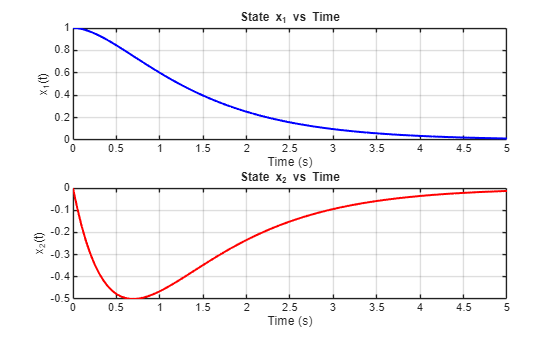

t_span = linspace(0, 5, 100); %from 0 to 5, 100 points inbetween
x_trajectory = zeros(2, length(t_span));

for i = 1:length(t_span)
    x_trajectory(:,i) = expm(A_exp * t_span(i)) * x0;
end

figure('Name', 'State Trajectory using Matrix Exponential');
subplot(2,1,1);
plot(t_span, x_trajectory(1,:), 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('x_1(t)');
title('State x_1 vs Time');

subplot(2,1,2);
plot(t_span, x_trajectory(2,:), 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('x_2(t)');
title('State x_2 vs Time');

Phase portrait

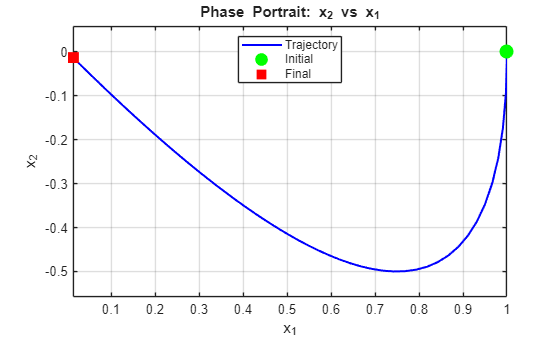

figure('Name', 'Phase Portrait');
plot(x_trajectory(1,:), x_trajectory(2,:), 'b-', 'LineWidth', 1.5);
hold on;
plot(x0(1), x0(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(x_trajectory(1,end), x_trajectory(2,end), 'rs', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
grid on;
xlabel('x_1');
ylabel('x_2');
title('Phase Portrait: x_2 vs x_1');
legend('Trajectory', 'Initial', 'Final', 'Location', 'best');
axis equal;


fprintf('\nSystem decays to zero (stable) as eigenvalues have negative real parts\n');


System decays to zero (stable) as eigenvalues have negative real parts


fprintf('Eigenvalues of A: ');

Eigenvalues of A: 

fprintf('%.4f ', eig(A_exp));

-1.0000 -2.0000 

fprintf('\n');

## Section 1.10: Summary and Key Takeaways

**Key Concepts Covered:**

- Matrix operations: addition, multiplication, transpose, concatenation

- Matrix properties: determinant, rank, trace, inverse, condition number

- Matrix norms: 1-norm, 2-norm, infinity-norm, Frobenius norm

- Triangular matrices: upper, lower, diagonal

- Linear equations: solving Ax=b, null space, orthogonality

- Eigenanalysis: eigenvalues, eigenvectors, characteristic polynomial

- Similarity transformations and invariants

- Jordan normal form for matrices with repeated eigenvalues

- Matrix exponential for solving linear differential equations

**MATLAB Functions Mastered:**

`eig`, `inv`, `det`, `rank`, `trace`, `norm`, `triu`, `tril`, `null`, `orth`, `dot`, `linsolve`, `poly`, `jordan`, `expm`

**Next Steps:**

These mathematical tools will be applied to:

- State-space modeling (Season 2)

- Controllability and observability analysis (Season 3)

- Stability analysis using Lyapunov theory (Season 5)

- Observer and controller design (Season 6)